# 运用Logistic Regression对titanic数据分类

clear;
clc

%% read in the data
Train = readtable('train.csv','Format','%f%f%f%q%s%f%f%f%q%f%q%s');
Test = readtable('test.csv','Format','%f%f%q%s%f%f%f%q%f%q%s');
disp(Train(1:5,[2:3 5:8 10:11]))

    Survived    Pclass       Sex        Age    SibSp    Parch     Fare       Cabin   
    ________    ______    __________    ___    _____    _____    ______    __________

       0          3       {'male'  }    22       1        0        7.25    {0×0 char}
       1          1       {'female'}    38       1        0      71.283    {'C85'   }
       1          3       {'female'}    26       0        0       7.925    {0×0 char}
       1          1       {'female'}    35       1        0        53.1    {'C123'  }
       0          3       {'male'  }    35       0        0        8.05    {0×0 char}




%% Sex information is quite important, we can use it to desigh the classifier
disp(grpstats(Train(:,{'Survived','Sex'}), 'Sex'))

                 Sex        GroupCount    mean_Survived
              __________    __________    _____________

    male      {'male'  }       577           0.18891   
    female    {'female'}       314           0.74204   




gendermdl = grpstats(Train(:,{'Survived','Sex'}), {'Survived','Sex'});
all_female = (gendermdl.GroupCount('0_male') + gendermdl.GroupCount('1_female'))...
    / sum(gendermdl.GroupCount)

all_female = 0.7868

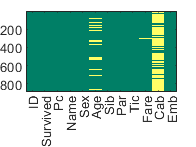


%% Data preprocessing. Some values are not available and others are not  reasonable
Train.Fare(Train.Fare == 0) = NaN;      % treat 0 fare as NaN
Test.Fare(Test.Fare == 0) = NaN;        % treat 0 fare as NaN
vars = Train.Properties.VariableNames;  % extract column names
figure
colormap(summer)
imagesc(ismissing(Train))
set(gca,'XTick', 1:12,'XTickLabel',{'ID','Survived','Pc','Name','Sex','Age','Sib','Par','Tic','Fare','Cab','Emb'});


%% fill in the missing ages with the average
avgAge = nanmean(Train.Age)             % get average age

avgAge = 29.6991

Train.Age(isnan(Train.Age)) = avgAge;   % replace NaN with the average
Test.Age(isnan(Test.Age)) = avgAge; 

%% fill in the missing fares according to their Pclass and then fill in the average of that Pclass
fare = grpstats(Train(:,{'Pclass','Fare'}),'Pclass');   % get class average
disp(fare)

         Pclass    GroupCount    mean_Fare
         ______    __________    _________

    1      1          216         86.149  
    2      2          184         21.359  
    3      3          491         13.788  



for i = 1:height(fare) % for each |Pclass|
    % apply the class average to missing values
    Train.Fare(Train.Pclass == i & isnan(Train.Fare)) = fare.mean_Fare(i);
    Test.Fare(Test.Pclass == i & isnan(Test.Fare)) = fare.mean_Fare(i);
end


%% about cabin
% tokenize the text string by white space
train_cabins = cellfun(@strsplit, Train.Cabin, 'UniformOutput', false);
test_cabins = cellfun(@strsplit, Test.Cabin, 'UniformOutput', false);

% count the number of tokens
Train.nCabins = cellfun(@length, train_cabins);
Test.nCabins = cellfun(@length, test_cabins);

% deal with exceptions - only the first class people had multiple cabins
Train.nCabins(Train.Pclass ~= 1 & Train.nCabins > 1,:) = 1;
Test.nCabins(Test.Pclass ~= 1 & Test.nCabins > 1,:) = 1;

% if |Cabin| is empty, then |nCabins| should be 0
Train.nCabins(cellfun(@isempty, Train.Cabin)) = 0;
Test.nCabins(cellfun(@isempty, Test.Cabin)) = 0;

%% fill in the Embarked with the most fequent Embarked place
% get most frequent value
disp(grpstats(Train(:,{'Survived','Embarked'}), 'Embarked'))

         Embarked    GroupCount    mean_Survived
         ________    __________    _____________

    S     {'S'}         644           0.33696   
    C     {'C'}         168           0.55357   
    Q     {'Q'}          77           0.38961   



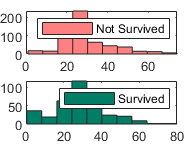


% apply it to missling value
for i = 1 : 891
	if isempty(Train.Embarked{i})
		Train.Embarked{i}='S';
	end
end

for i = 1 : 418
	if isempty(Test.Embarked{i})
		Test.Embarked{i}='S';
	end
end

% convert the data type from categorical to double
Train.Embarked = double(cell2mat(Train.Embarked));
Test.Embarked = double(cell2mat(Test.Embarked));

%% type of Set changed from logic to double
for i = 1 : 891
	if strcmp(Train.Sex{i} ,'male')
		Train.Sex{i}=1;
	else
		Train.Sex{i}=0;
	end
end

for i = 1 : 418
	if strcmp(Test.Sex{i} ,'male')
		Test.Sex{i}=1;
	else
		Test.Sex{i}=0;
	end
end
Train.Sex = cell2mat(Train.Sex);
Test.Sex = cell2mat(Test.Sex);

%% del some non useful features

Train(:,{'Name','Ticket','Cabin'}) = [];
Test(:,{'Name','Ticket','Cabin'}) = [];

%% feature analysis
 figure
 subplot(2,1,1)
 colormap(summer)
hist (Train.Age(Train.Survived == 0))   % age histogram of non-survivers
h = findobj(gca,'Type','patch');
set(h,'FaceColor',[1 .5 .5])
legend('Not Survived');

subplot(2,1,2)
hist (Train.Age(Train.Survived == 1))   % age histogram of survivers
legend('Survived');


%% train and test set
Y_train = Train.Survived;                   % slice response variable
X_train = Train(:,3:end);                   % select predictor variables
vars = X_train.Properties.VariableNames;    % get variable names
X_train = table2array(X_train);             % convert to a numeric matrix
X_test = table2array(Test(:,2:end));        % convert to a numeric matrix

# 构造训练样本和测试样本。

X_train = X_train'; 
num_of_train = round(891*0.7);
idx = randperm(891);
X = X_train(:,idx(1:num_of_train));
X = [X;ones(1,num_of_train)];
Y = Y_train(idx(1:num_of_train))';
X_test = X_train(:,idx(num_of_train+1:end));
X_test = [X_test;ones(1,891-num_of_train)];
Y_test = Y_train(idx(num_of_train+1:end))';

# 梯度下降法求解Logistic Regression

% W = pinv(X')*Y;
W = rand(9,1);
for i = 1 : 30000
    alphak = 0.001;
    temp = my_grad(W,X,Y);
    W = W - alphak * my_grad(W,X,Y);
    f(i) = my_fun(W,X,Y);
end

# 画损失函数的收敛曲线

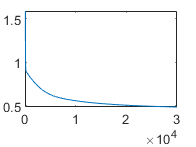

figure;
plot(f)


for i = 1 : 891-num_of_train
    y_pred(i) = my_sig(W,X_test(:,i));
end

y_pred_label = y_pred >0.5;
num_correct = sum(Y_test == double(y_pred_label));
Accuracy = num_correct/(891-num_of_train);
disp(['The accuracy is' num2str(Accuracy)])

The accuracy is0.76779


# 画属于第一类的后验概率杆状图

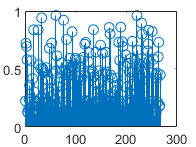

figure

stem(y_pred)